Author: **Arjan Gupta**

Due: March 27, 2023

Class: RBE 501

Institution: Worcester Polytechnic Institute

# Forward Dyanamics of Three Link Manipuator

clear; clc; close all;

## Create Rigid Body Elements

First, let us create a `rigidBodyTree` robot model.

robot = rigidBodyTree("DataFormat","column");
base = robot.Base;

Then, create a series of linkages as `rigidBody` objects. The robot 3 rectangular arms.

rotatingBase = rigidBody("rotating_base");
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");
gripper = rigidBody("gripper");

Create collision objects for each rigid body with different shapes and dimensions. When you create the collision objects, the coordinate frame is centered in the middle of the object by default. Set the `Pose` property to move the frame to the bottom of each body along the *z*-axis. Model the gripper as a sphere for simplicity.

coll1 = collisionBox(0.01,0.02,0.15); % box: length, width, height (x,y,z)
coll1.Pose = trvec2tform([0 0 0.15/2]);
coll2 = collisionBox(0.01,0.02,0.15); % box: length, width, height (x,y,z)
coll2.Pose = trvec2tform([0 0 0.15/2]);
coll3 = collisionBox(0.01,0.02,0.15); % box: length, width, height (x,y,z)
coll3.Pose = trvec2tform([0 0 0.15/2]);

Add the collision bodies to the rigid body objects.

addCollision(arm1,coll1)
addCollision(arm2,coll2)
addCollision(arm3,coll3)

## Attach Joints

Each rigid body is attached using a revolute joint. Create the `rigidBodyJoint` objects for each body. Specify the *x*-axis as the axis of rotation for the rectangular arm joints. Specify the *y*-axis for the gripper. The default axis is the *z*-axis. 

jnt1 = rigidBodyJoint("jnt1","revolute");
jnt2 = rigidBodyJoint("jnt2","revolute");
jnt3 = rigidBodyJoint("jnt3","revolute");

jnt1.JointAxis = [0 0 1]; % x-axis
jnt2.JointAxis = [0 0 1];
jnt3.JointAxis = [0 0 1];

In the prompt of this assignment, we are given the following table.


$$\matrix{
\text{Link}    	& a_i 	& \alpha_i &  d_i & \theta_i  \cr
1			& 0 			& 0	& 0	& \theta_1			\cr
2			& 0 			& L_1		& 0	& \theta_2		\cr
3			& 0 			& L_2			& 0 & \theta_3	\cr
}$$


% Joint variables
theta1 = 0;
theta2 = 0;
theta3 = 0;
% Link lengths
L1 = 4;
L2 = 3;
L3 = 2;
% Masses
m1 = 20;
m2 = 15;
m3 = 10;
% Moments of inertia
I1 = 0.5;
I2 = 0.2;
I3 = 0.1;
% DH table
dhparams = [0 0  0 theta1;
            0 L1 0 theta2;
            0 L2 0 theta3];
setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');

## Assemble Robot

Create an object array for both the bodies and joints, including the original base. Add each joint to the body, and then add the body to the tree. Visualize each step.

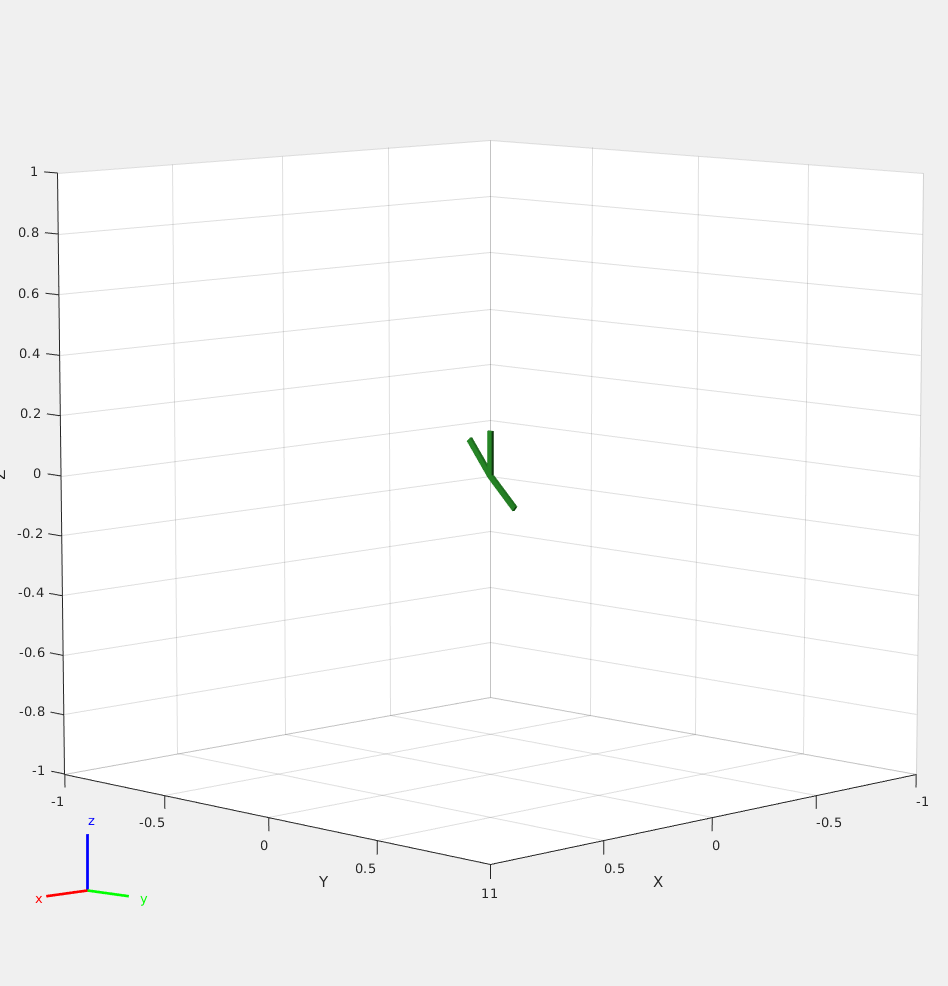

bodies = {base,arm1,arm2,arm3};
joints = {[],jnt1,jnt2,jnt3};

figure("Name","Assemble Robot","Visible","on")
for i = 2:length(bodies) % Skip base. Iterate through adding bodies and joints.
    bodies{i}.Joint = joints{i};
    addBody(robot,bodies{i},bodies{i-1}.Name)
    show(robot,"Collisions","on","Frames","off");
    drawnow;
end

## Problem 1

In this problem we implement the forward dynamics and plot the joint accelerations and velocities in response to actuator torques.

To calculate forward dynamics, we first specify some parameters.

% Set data format
three_rev_robot.DataFormat = 'col';
% Set gravity direction
three_rev_robot.Gravity = [0; -9.81; 0];
% Starting configuration
q = homeConfiguration(three_rev_robot);

Check for incorrect argument data type or missing argument in call to function 'homeConfiguration'.

Now we calculate the forward dynamics.